# Testing different numerical differentiation formulas

Comparison between MATLAB default differentiation function `diff` and numerical formulas using finite differentiation, such as 

1. forwards difference


$$f'(x) = \frac{f(x+h) - f(x)}{h}$$


2. backwards difference


$$f'(x) = \frac{f(x) - f(x-h)}{h}$$


3. central difference


$$f'(x) = \frac{f(x+h) - f(x-h)}{2h}$$


% Test functions
syms x
f1 = -0.1*x^4 - 0.15*x^3 - 0.5*x^2 - 0.25*x + 1.2;
f2 = x^6 - 1;

n = 100;
t = 0:0.5:n/2;
h = 0:10;
l = strings([1 length(h)]);
u = zeros([1 n]);


## Standard MATLAB `diff` function

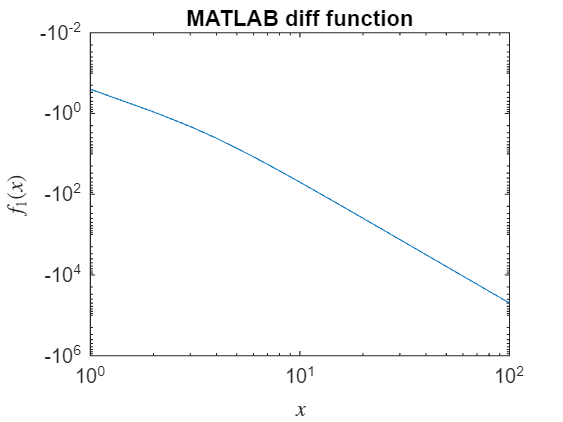

f1P = diff(f1);
f2P = diff(f2);
y = zeros([1 n]);

parfor i = 1:n
    y(i) = subs(f1P, x, t(i));
end

loglog(y)
title('MATLAB diff function')
xlabel('$x$', 'interpreter','latex')
ylabel('$f_1(x)$', 'interpreter','latex')

## Forwards difference

Using $f'(x) = \frac{f(x+h) - f(x)}{h}$, we'll approximate the derivative, using different $h$ parameters, starting from 0.1 to test if diminishing $h$ does has a difference in the error or not

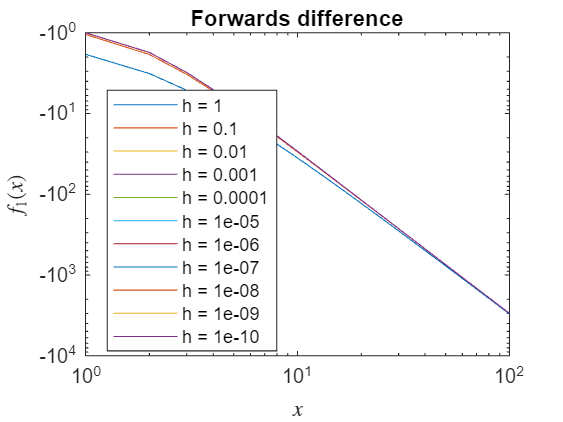

for i = 1:length(h)
    p = 1*0.1^h(i);
    l(i) = 'h = ' + string(p);

    parfor j = 1:n
        u(j) = (subs(f1P, x, t(j)+p) - subs(f1P, x, t(j))) ...
            / p;
    end
    
    loglog(u)
    if i == 1
        hold on
    end
end

title('Forwards difference')
xlabel('$x$','interpreter','latex')
ylabel('$f_1(x)$','interpreter','latex')
legend(l, "Location", 'best')
hold off

## Backwards difference

Repeating the past experiment, but this time using the backwards difference formula $f'(x) = \frac{f(x) - f(x-h)}{h}$

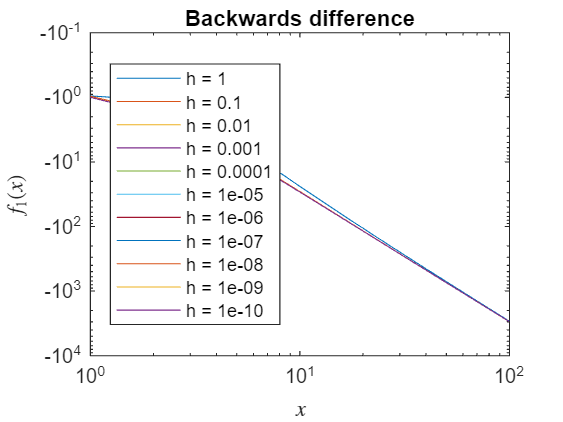

for i = 1:length(h)
    p = 1*0.1^h(i);
    l(i) = 'h = ' + string(p);

    parfor j = 1:n
        u(j) = (subs(f1P, x, t(j)) - subs(f1P, x, t(j) - p)) ...
            / p;
    end
    
    loglog(u)
    if i == 1
        hold on
    end
end

title('Backwards difference')
xlabel('$x$','interpreter','latex')
ylabel('$f_1(x)$','interpreter','latex')
legend(l, "Location", 'best')
hold off

## Central difference

Same as past two experiments, but now using the central difference formula, defined as  $f'(x) = \frac{f(x+h) - f(x-h)}{2h}$

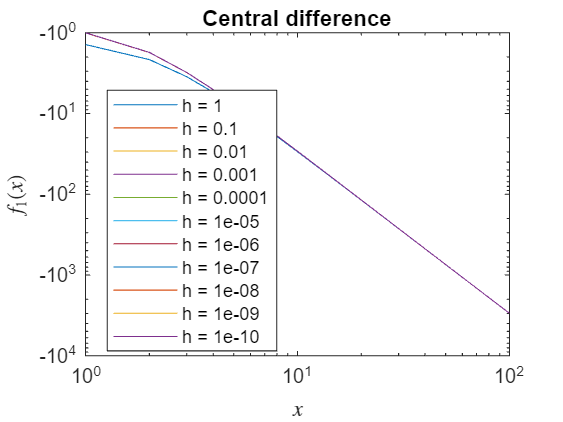

for i = 1:length(h)
    p = 1*0.1^h(i);
    l(i) = 'h = ' + string(p);

    parfor j = 1:n
        u(j) = (subs(f1P, x, t(j) + p) - subs(f1P, x, t(j) - p)) ...
            / (2*p);
    end
    
    loglog(u)
    if i == 1
        hold on
    end
end

title('Central difference')
xlabel('$x$','interpreter','latex')
ylabel('$f_1(x)$','interpreter','latex')
legend(l, "Location", 'best')
hold off